Consider the confound of age.

Mean: ratio of age mean between sites

Variance: ratio of age variance between sites

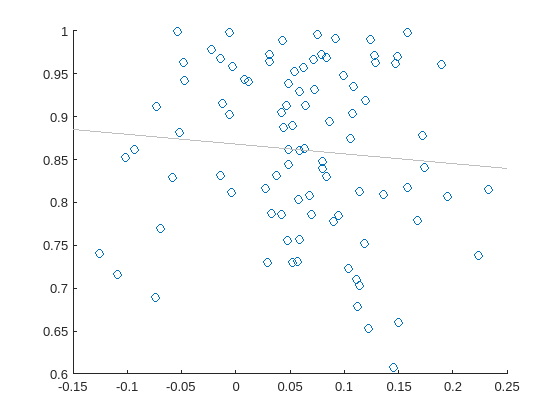

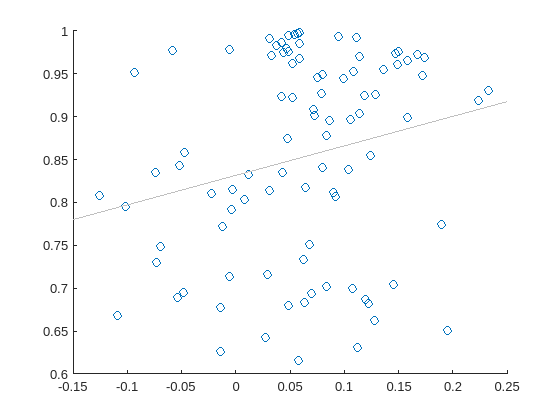

BD


                       Mean      Variance
                     ________    ________

    spearman corr    -0.10025    0.16882 
    p                 0.28211      0.142 



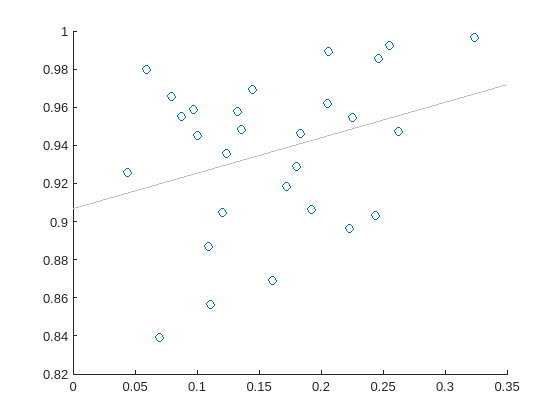

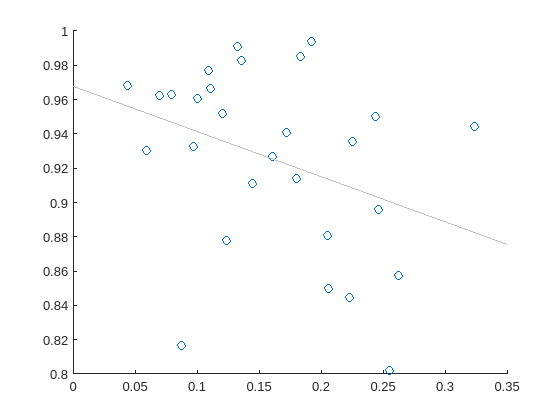

SCA


                      Mean      Variance
                     _______    ________

    spearman corr    0.26273    -0.36125
    p                 0.1716    0.093261



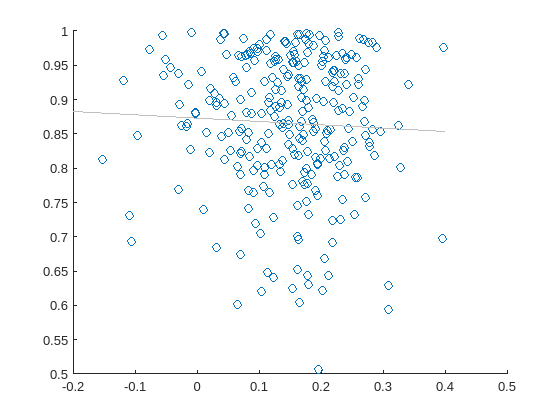

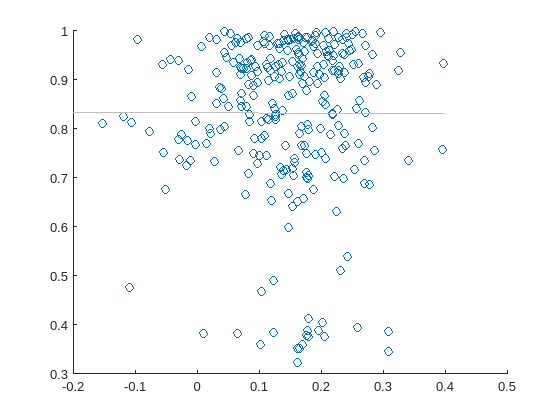

SCZ


                       Mean       Variance
                     _________    ________

    spearman corr    -0.033388    0.03978 
    p                  0.40883    0.36823 



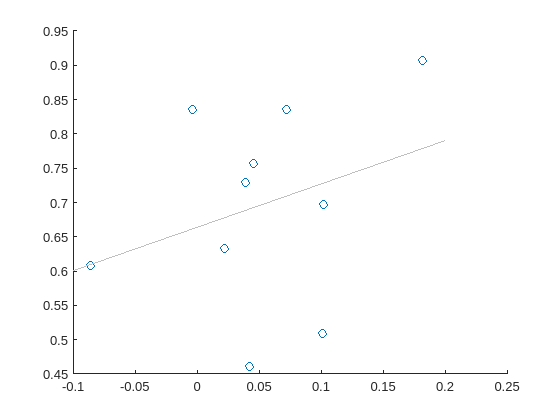

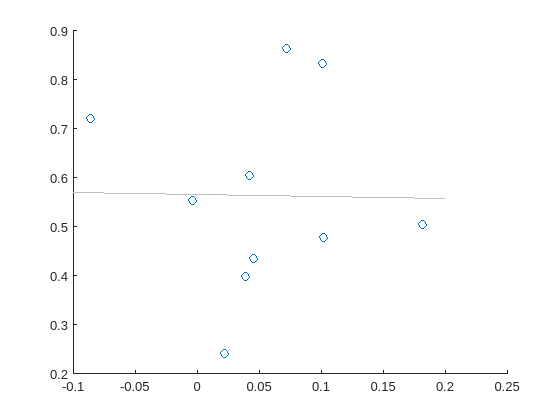

ASD


                      Mean      Variance
                     _______    ________

    spearman corr    0.28485    0.11515 
    p                0.22588    0.47047 



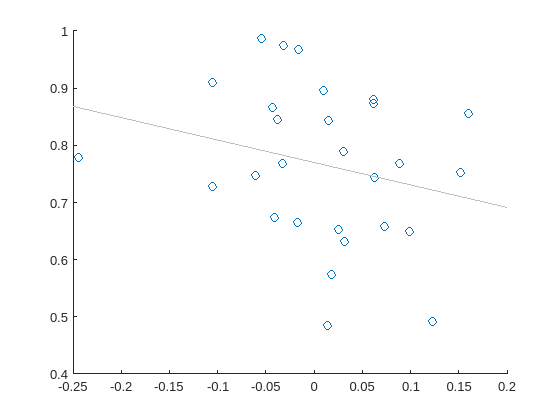

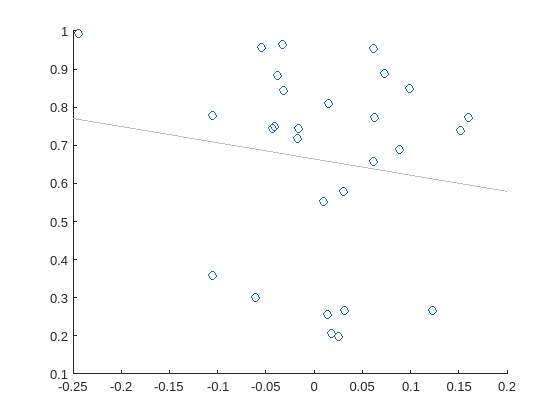

MDD


                       Mean      Variance
                     ________    ________

    spearman corr    -0.30925    -0.18227
    p                 0.06767     0.25276



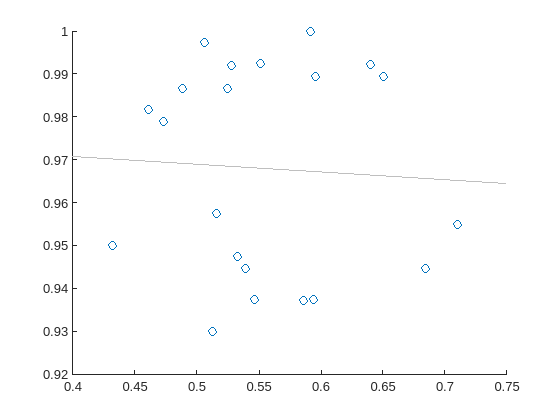

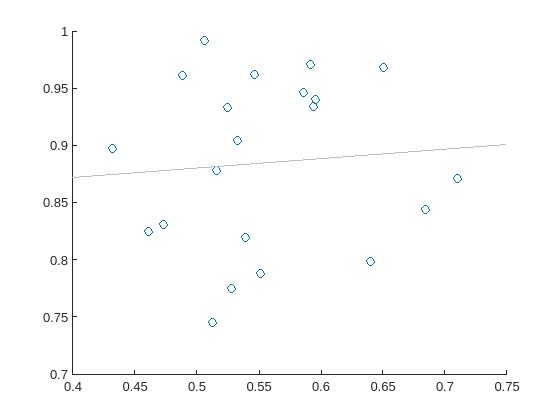

AD


                       Mean      Variance
                     ________    ________

    spearman corr    0.011688    0.11558 
    p                 0.46742     0.3247 



% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataSBM_extended.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag', 'corSig', 'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to Euler number similarity between sites
    [varTable{iDiag}, meanAge{iDiag}, stdAge{iDiag}, nSite{iDiag}]= cor_var_age(metadata, diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag}, iter, type);
    % Display results for the current diagnosis
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end

% Suppress warnings related to the last operation
warning('off', 'last');

% Save results to a .mat file
save('output/confound_age.mat','varTable', 'meanAge', 'stdAge','nSite')